Двойное быстрое синус-преобразование

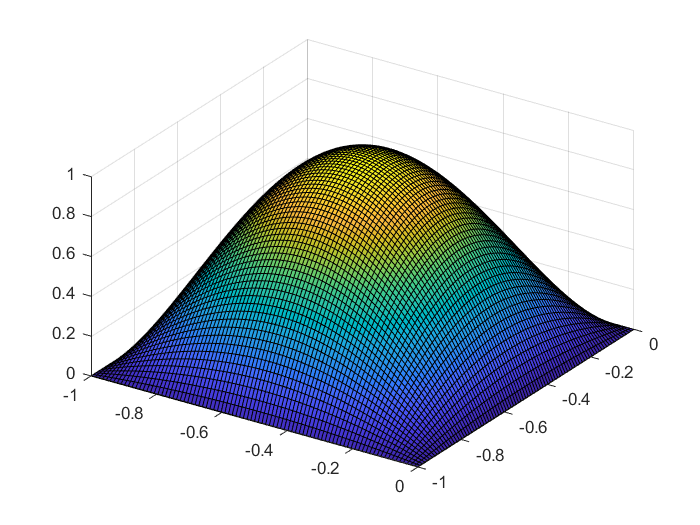

clc;
clear all;
steps = 88;
step = 1 / steps;
f = zeros(1, (steps - 1) * (steps - 1));
f1 = zeros((steps - 1), (steps - 1));
for iy = 1 : steps - 1
    for ix = 1 : steps - 1
        f(1, (iy - 1) * (steps - 1) + ix) = 32 * step.^3 * ...
        (ix * (1 - ix * step) + iy * (1 - iy * step));
        f1(ix, iy) = 32 * step.^3 * ...
        (ix * (1 - ix * step) + iy * (1 - iy * step));
%       f(1, (iy - 1) * (steps - 1) + ix) = 50 * iy ...
%           * (1 - iy * step) * (1 - ix * step) * step * ix * step;  
%         f(ix, iy) = 50 * iy * (1 - iy * step) * (1 - ix * step) * step * ix * step; 
%       f(ix, iy) = 32 * step * ...
%         (ix * (1 - ix * step) + iy * (1 - iy * step));
    end
end
% multiply by W^(-1)
u1 = idst(f1);
u1 = u1';
u1 = idst(u1) / step.^2;
% t = idst(idst(f));
% multiply by D^(-1)
% lambda = zeros(1, (steps - 1) * (steps - 1));
% for m = 1 : steps - 1
%     for k = 1 : steps - 1
%         lambda(1, (m - 1) * (steps - 1) + k) = step.^2 / (4 * (sin(pi * k * step * 0.5)).^2 + 4 * ...
%         (sin(pi * m * step * 0.5)).^2);
%     end
% end
lambda = zeros((steps - 1), (steps - 1));
for m = 1 : steps - 1
    for k = 1 : steps - 1
        lambda(k, m) = step.^2 / (4 * (sin(pi * k * step * 0.5)).^2 + 4 * ...
        (sin(pi * m * step * 0.5)).^2);
    end
end
u2 = lambda .* u1;
% multiply by W
% u = dst(dst(u2));
u = dst(u2);
u = u';
u = dst(u);
[X,Y] = meshgrid(0:step:1,0:step:1);
U = zeros(steps + 1, steps + 1);
% for iy = 1 : steps - 1
%     for ix = 1 : steps - 1
%         U(ix + 1, iy + 1) = u(1, (iy - 1) * (steps - 1) + ix);
%     end
% end
for iy = 1 : steps - 1
    for ix = 1 : steps - 1
        U(ix + 1, iy + 1) = u(ix, iy);
    end
end
surf(X,Y,U);

Метод Якоби

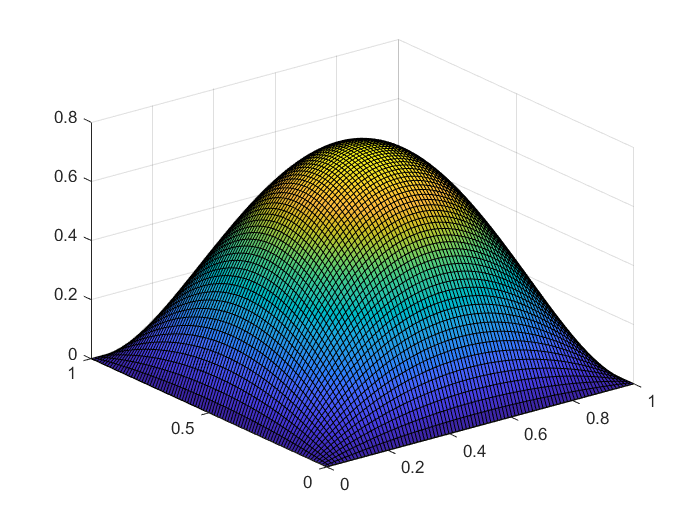

D = zeros(1, (steps - 1) * (steps - 1));
for m = 1 : steps - 1
    for k = 1 : steps - 1
        D(1, (m - 1) * (steps - 1) + k) = 1 / 4;
    end
end
E = -1 * eye(steps - 1);
C = zeros(steps - 1);
for i = 1 : (steps - 1)
    for j = 1 : (steps - 1)
        if i - j == 1 || j - i == 1
            C(i, j) = -1;
        end
    end
end
A = zeros((steps - 1) * (steps - 1), (steps - 1) * (steps - 1));
for i = 1 : (steps - 1)
    for j = 1 : (steps - 1)
        if i - j == 1 || j - i == 1
            A((i - 1) * (steps - 1) + 1 : i  * (steps - 1), (j - 1) * (steps - 1) + 1 : j  * (steps - 1) ) = E;
        end
        if i == j 
            A((i - 1) * (steps - 1) + 1 : i  * (steps - 1), (j - 1) * (steps - 1) + 1 : j  * (steps - 1) ) = C;
        end
    end
end
% A
res = zeros(1, (steps - 1) * (steps - 1));
itterations =2400;
for k = 1 : itterations
    res = D .* f - D .* (res * A);
end

RES = zeros(steps + 1, steps + 1);
for iy = 1 : steps - 1
    for ix = 1 : steps - 1
        RES(ix + 1, iy + 1) = res(1, (iy - 1) * (steps - 1) + ix);
    end
end
surf(X,Y,RES);